%--------------------------
%cd('C:\Users\xy123\Matlab\Nlab_matlab/Exp2');

%-----------------------------------
% Acitivate at Exp2/
resultthree = "resultthree/";
resultmitsuba = "resultmitsuba/";
ana_result = "analysis/";
exp1path = "../test/";
exp2path = "./";

rowNames = {'cu_0.025', 'cu_0.129', 'pla_0.075', 'pla_0.225'};
rowNames2 = {'cu-0.025', 'cu-0.129', 'pla-0.075', 'pla-0.225'};
colNames = [19, 39, 78, 80, 102, 125, 152, 203, 226, 227, 230, 232, 243, 278, 281];

%-----------------------------------
% Exp1
%-----------------------------------
Exp1mitsubaMatrix = zeros(4, 15);

%allfileload
dirInfo = dir(exp1path + resultmitsuba);
filesNames = {dirInfo(~ismember({dirInfo(:).name}, {'.', '..'})).name};
numFiles = sum(~ismember({dirInfo(:).name}, {'.', '..'}));

for foldernum =1:numFiles
    filename = fullfile(exp1path + resultmitsuba, filesNames{foldernum});
    disp(filename);
    for materialnum = 1:length(rowNames)
        sheetName = rowNames{materialnum};
        sheetData = readtable(filename, 'Sheet', sheetName, 'ReadVariableNames', false);
        
        names = sheetData{:, 1};
        scores = sheetData{:, 2};
        
        for i = 1:length(names)
            nameStr = names{i};
            idStr = regexp(nameStr, '\d+', 'match');
            idNum = str2double(idStr(end));
            colIndex = find(colNames == idNum);
            rowIndex = find(strcmp(rowNames, sheetName));
            if ~isempty(colIndex) && ~isempty(rowIndex)
                Exp1mitsubaMatrix(rowIndex, colIndex) = Exp1mitsubaMatrix(rowIndex, colIndex) + scores(i);
            end
        end
    end
end

..\test\resultmitsuba\kawahara_mitsuba.xlsx
..\test\resultmitsuba\killian_mitsuba.xlsx
..\test\resultmitsuba\kyou_mitsuba.xlsx
..\test\resultmitsuba\miyoshi_mitsuba.xlsx
..\test\resultmitsuba\okamoto_mitsuba.xlsx
..\test\resultmitsuba\satou_mitsuba.xlsx


Exp1mitsubaMatrix = Exp1mitsubaMatrix ./ numFiles;

error_exp1 = std(Exp1mitsubaMatrix, 0, 2)/ sqrt(size(Exp1mitsubaMatrix, 2));
error_exp1 = repmat(error_exp1, 1, 15);


%-----------------------------------
% Exp2
%-----------------------------------
Exp2RowMatrix = zeros(4, 15);

%allfileload
dirInfo = dir(exp2path + resultmitsuba);
filesNames = {dirInfo(~ismember({dirInfo(:).name}, {'.', '..'})).name};
numFiles = sum(~ismember({dirInfo(:).name}, {'.', '..'}));

for foldernum =1:numFiles
    filename = fullfile(exp2path + resultmitsuba, filesNames{foldernum});
    disp(filename);
    for materialnum = 1:length(rowNames)
        sheetName = rowNames{materialnum};
        sheetData = readtable(filename, 'Sheet', sheetName, 'ReadVariableNames', false);
        
        names = sheetData{:, 1};
        scores = sheetData{:, 2};
        
        for i = 1:length(names)
            nameStr = names{i};
            idStr = regexp(nameStr, '\d+', 'match');
            idNum = str2double(idStr(end));
            colIndex = find(colNames == idNum);
            rowIndex = find(strcmp(rowNames, sheetName));
            if ~isempty(colIndex) && ~isempty(rowIndex)
                Exp2RowMatrix(rowIndex, colIndex) = Exp2RowMatrix(rowIndex, colIndex) + scores(i);
            end
        end
    end
end

.\resultmitsuba\kawahara_mitsuba_exp2.xlsx
.\resultmitsuba\killian_mitsuba_exp2.xlsx
.\resultmitsuba\kyou_mitsuba_exp2.xlsx
.\resultmitsuba\miyoshi_mitsuba_exp2.xlsx
.\resultmitsuba\okamoto_mitsuba_exp2.xlsx
.\resultmitsuba\satou_mitsuba_exp2.xlsx


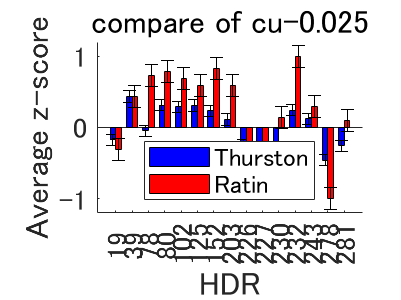

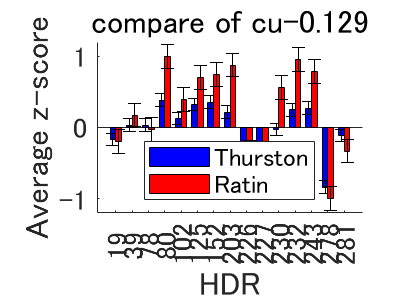

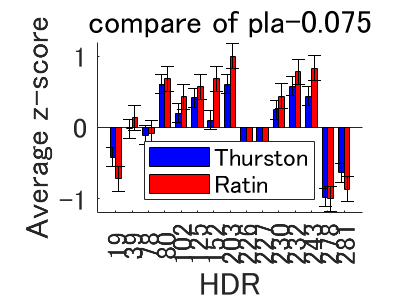

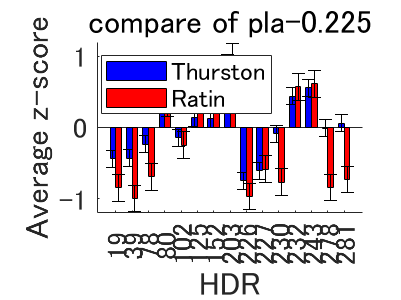

Exp2RowMatrix = Exp2RowMatrix ./ (numFiles*5);

%exp2 z-score
%{
Exp2mitsubaMatrix = zeros(size(Exp2RowMatrix));
%{
for i = 1:size(Exp2RowMatrix, 1)
    rowData = Exp2RowMatrix(i, :);
    rowMean = mean(rowData);
    rowStd = std(rowData);
    Exp2Row2Matrix(i, :) = (rowData - rowMean) / rowStd;
end
%}
for i = 1:size(Exp2RowMatrix, 1)
    Exp2mitsubaMatrix(i, :) = zscore(Exp2RowMatrix(i, :));
end
%}


Exp2Row2Matrix = zeros(size(Exp2RowMatrix));
for i = 1:size(Exp2RowMatrix, 1)
    Exp2Row2Matrix(i, :) = zscore(Exp2RowMatrix(i, :));
end

Exp2mitsubaMatrix = zeros(size(Exp2Row2Matrix));
for i = 1:size(Exp2Row2Matrix, 1)
    row_min = min(Exp2Row2Matrix(i, :));
    row_max = max(Exp2Row2Matrix(i, :));
    
    Exp2mitsubaMatrix(i, :) = 2 * (Exp2Row2Matrix(i, :) - row_min) / (row_max - row_min)-1;
end

error_exp2 = std(Exp2mitsubaMatrix, 0, 2)/ sqrt(size(Exp2mitsubaMatrix, 2));
error_exp2 = repmat(error_exp2, 1, 15);

%-----------------------------------
% z-score graph
%-----------------------------------
%bar graph
for row = 1:4
    figure;
    hold on;
    bar_width = 0.35;
    x = 1:length(colNames);

    % exp1のプロット
    b1 = bar(x - bar_width/2, Exp1mitsubaMatrix(row, :), bar_width, 'FaceColor', 'b', 'DisplayName', 'Thurston'); 
    h1 = errorbar(x - bar_width/2, Exp1mitsubaMatrix(row, :), error_exp1(row,:), 'k', 'linestyle', 'none');
    
    % exp2のプロット
    b2 = bar(x + bar_width/2, Exp2mitsubaMatrix(row, :), bar_width, 'FaceColor', 'r', 'DisplayName', 'Rating'); 
    h2 = errorbar(x + bar_width/2, Exp2mitsubaMatrix(row, :), error_exp2(row,:), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(colNames));
    set(gca, 'XTickLabel', colNames, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Average z-score', 'FontSize', 16);
    title(['compare of ' rowNames2{row}], 'FontSize', 16);
    %legend('show', 'Location', 'southwest');
    legend([b1, b2], {'Thurston', 'Ratin'}, 'Location', 'best');

    plotname = strcat(ana_result, '/', rowNames2{row}, '.jpg');
    saveas(gcf, plotname);
    hold off;
end


%correlation_coefficients
correlation_coefficients = zeros(1, 4);
for row = 1:4
    data_exp1 = Exp1mitsubaMatrix(row, :);
    data_exp2 = Exp2mitsubaMatrix(row, :);
    corr_matrix = corrcoef(data_exp1, data_exp2);
    correlation_coefficients(row) = corr_matrix(1, 2);
end

disp(correlation_coefficients);

    0.8124    0.9297    0.9594    0.8459





%-----------------------------------
% ranking
%-----------------------------------
%{
Exp1_rank_matrix = zeros(4,15);
for row = 1:size(Exp1mitsubaMatrix, 1)
    [~, rank] = sort(Exp1mitsubaMatrix(row, :),'descend');
    Exp1_rank_matrix(row, rank) = 1:length(rank);
end

%rank
Exp2_rank_matrix = zeros(4,15);
for row = 1:size(Exp2RowMatrix, 1)
    [~, rank] = sort(Exp2RowMatrix(row, :),'descend');
    Exp2_rank_matrix(row, rank) = 1:length(rank);
end

Exp1table = {};
Exp2table = {};

for row = 1:4
    %Exp1
    exp1rank = round(Exp1mitsubaMatrix(row,:),3);
    [exp1rank, sortIndex] = sort(exp1rank,'descend'); 
    exp1rankname = colNames(sortIndex);
    exp1rank_t = [exp1rankname;exp1rank]';
    rowname = {'HDR',rowNames2{row}};
    exp1cell = cat(1,rowname,num2cell(exp1rank_t));
    Exp1table = cat(2,Exp1table,exp1cell);

    %mitsuba
    exp2rank = round(Exp2RowMatrix(row,:),3);
    [exp2rank, sortIndex] = sort(exp2rank,'descend'); 
    exp2rankname = colNames(sortIndex);
    exp2rank_t = [exp2rankname;exp2rank]';
    rowname = {'HDR',rowNames2{row}};
    exp2cell = cat(1,rowname,num2cell(exp2rank_t));
    Exp2table = cat(2,Exp2table,exp2cell);
end

SaveFileName = strcat(ana_result, '/average_ranking.xlsx');
Exp1table = cell2table(Exp1table, 'VariableNames', {'1','2','3','4','5','6','7','8'});
writetable(Exp1table,SaveFileName,'Sheet','Exp1');

Exp2table = cell2table(Exp2table, 'VariableNames', {'1','2','3','4','5','6','7','8'});
writetable(Exp2table,SaveFileName,'Sheet','Exp2');

%-----------------------------------
% Rank Graph Plot
%-----------------------------------
%bar graph
for row = 1:4
    figure;
    bar_width = 0.35;
    x = 1:length(colNames);

    % exp1のプロット
    bar(x - bar_width/2, Exp1_rank_matrix(row, :), bar_width, 'FaceColor', 'b', 'DisplayName', 'Thurston'); 
    hold on;
    
    % exp2のプロット
    bar(x + bar_width/2, Exp2_rank_matrix(row, :), bar_width, 'FaceColor', 'r', 'DisplayName', 'scaling'); 
    
    ylim([0,16]);
    set(gca, 'XTick', 1:length(colNames));
    set(gca, 'XTickLabel', colNames, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('rank', 'FontSize', 16);
    title(['compare of ' rowNames2{row}], 'FontSize', 16);
    %legend('show', 'Location', 'southwest');

    plotname = strcat(ana_result, '/', rowNames2{row}, '.jpg');
    saveas(gcf, plotname);
    hold off;
end
%-----------------------------------
% Coef Spearman
%-----------------------------------
spearmanCorr = zeros(4, 1);

for row = 1:4
    spearmanCorr(row) = corr(Exp1mitsubaMatrix(row, :)', Exp2RowMatrix(row, :)', 'Type', 'Spearman');
    kendallW(row) = corr(Exp1mitsubaMatrix(row, :)', Exp2RowMatrix(row, :)', 'Type', 'Kendall');
end

disp('スピアマン順位相関係数:');
disp(spearmanCorr);
disp('ケントール順位相関係数:');
disp(kendallW);
%}

